## **Etapa 1 - Atividades**

#### 1) Elaboração do diagrama do modelo eletrodinâmico do circuito WPT

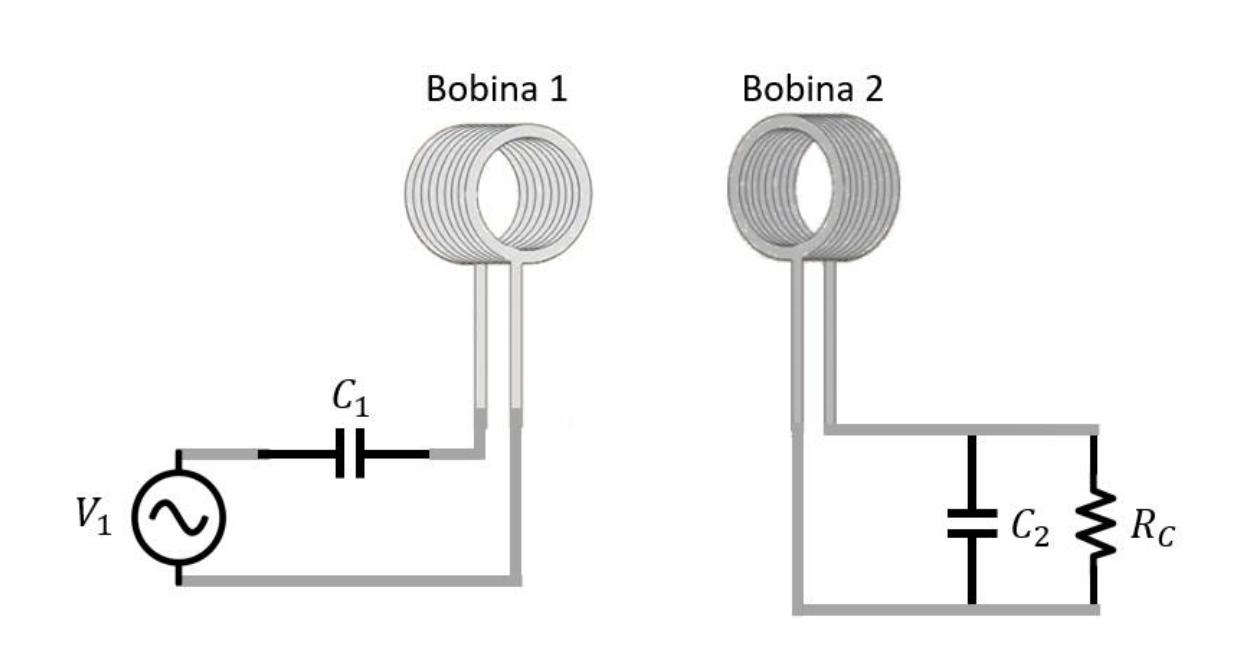

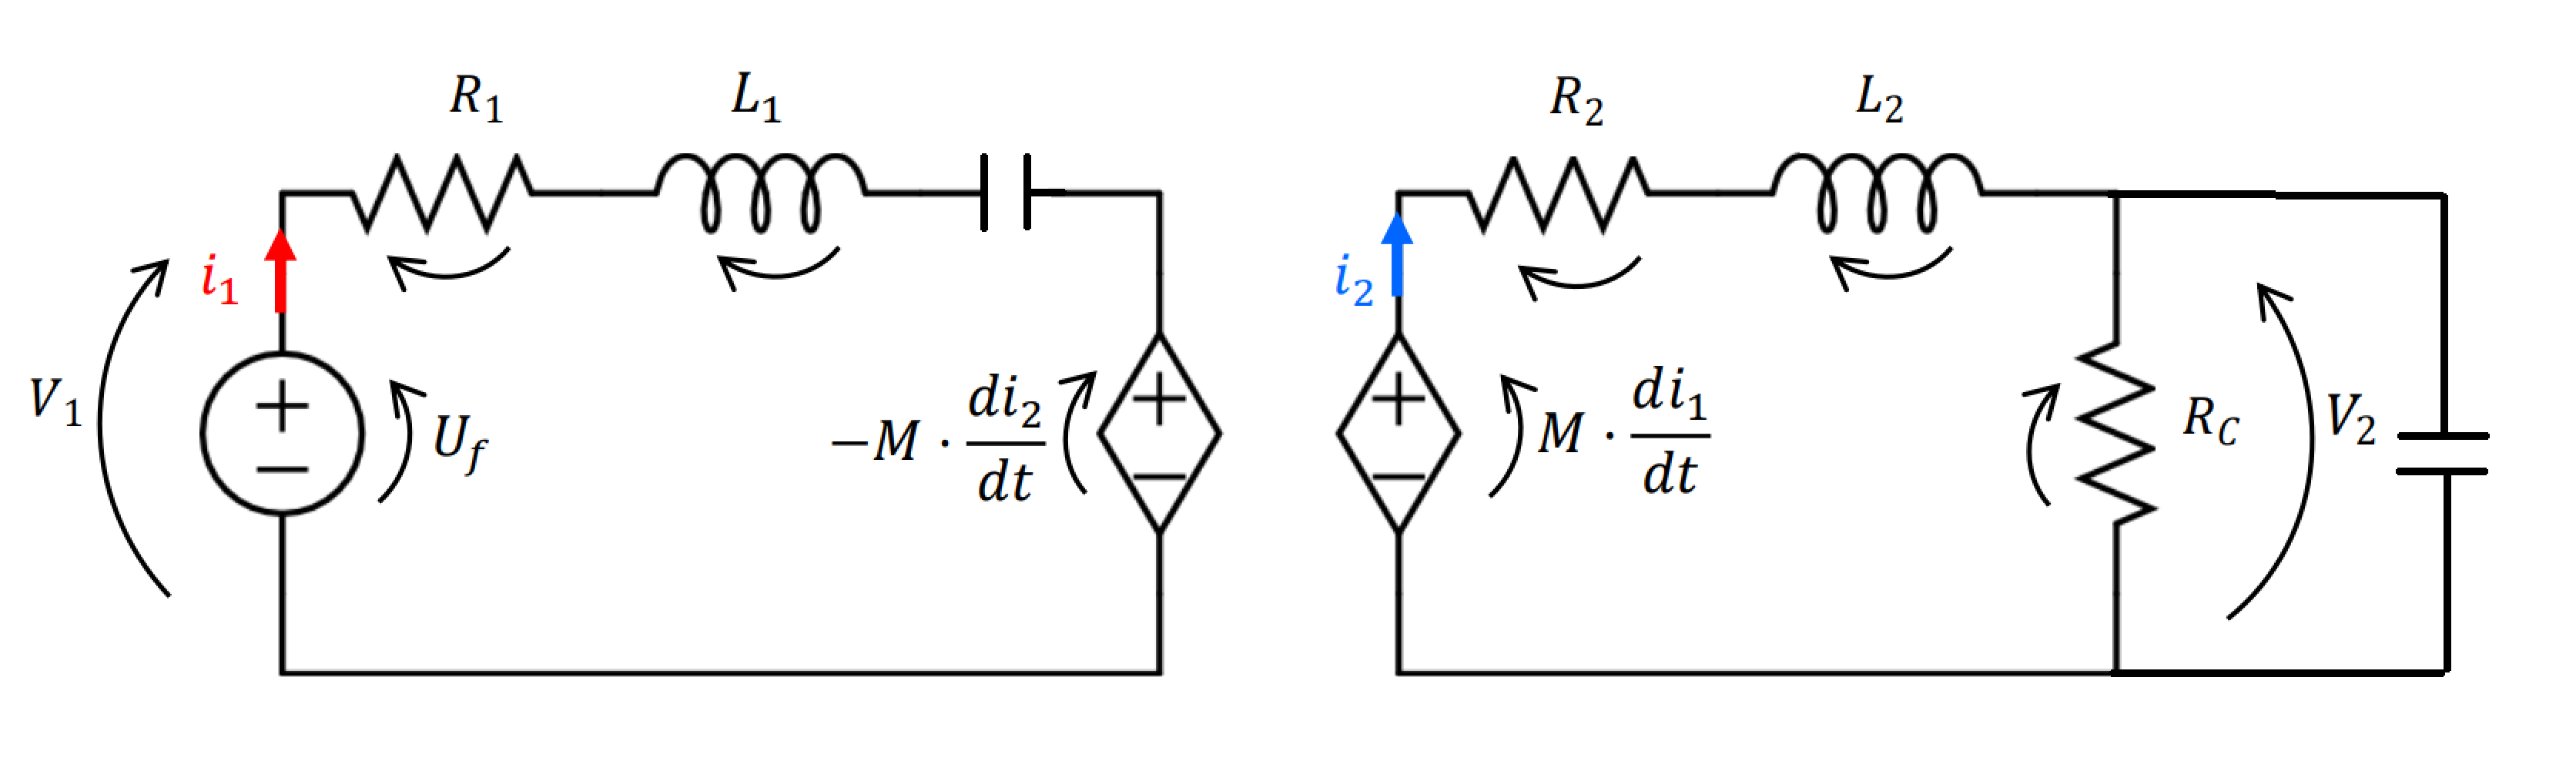

                                   Frequência de ressonancia para cirtuico LC

                                                    f = 1 / (2π √L C)

#### 2) Código do modelo numérico

function  CalcularTransformador(v1,rc,r1,freq,k,r2)=
    %Frequência angular
    w = 2*pi*freq
    
    %Reatâncias indutivas de L1
    xl1 = 1j*w*L1     
    
    %Reatâncias indutivas de L2
    xl2 = 1j*w*L2
    
    %Indutância Mútua
    M = k*(sqrt(L1*L2))
    %Reatâncias indutivas mútua
    xm = 1j*w*M      
    Z=np.array([[r1+xl1, -xm],[-xm, xl2+r2+rc]])
    V=np.array([v1,0])
    I=np.dot(linalg.inv(Z),V)
    return I[0], I[1]